clear; clc; close all;

% DH-parametre
[alpha_1, alpha_4] = deal(-pi/2, pi/2);
[alpha_2, alpha_3, alpha_5] = deal(0);
[a1, a2, a3, a4, a5] = deal(0, 0.35, 0.30, 0, 0);
[d1, d2, d3, d4, d5] = deal(0.2, 0, 0, 0.2, 0.05);

%      [theta d a alpha sigma]
L1 = Link([0 d1 a1 alpha_1 0]);
L2 = Link([0 d2 a2 alpha_2 0]);
L3 = Link([0 d3 a3 alpha_3 0]);
L4 = Link([0 d4 a4 alpha_4 0]);
L5 = Link([0 d5 a5 alpha_5 0]);
L2.offset = -pi/2;
L4.offset =  pi/2;

% Sett sammen til et SerialLink-objekt
robot = SerialLink([L1 L2 L3 L4 L5], 'name', '5DOF');

% HÅV
robot.tool = transl(0, 0, 0.20); % håven stikker 20 cm ut fra håndleddet

% BÅT
boat_length = 1.0;
boat_width  = 0.4;
boat_height = 0.2;

x = [-boat_length/2, boat_length/2];
y = [-boat_width/2,  boat_width/2];
z = [0, boat_height];
[X, Y, Z] = ndgrid(x, y, z);

faces = [
    1 3 4 2;  % topp
    1 2 6 5;  % side 1
    2 4 8 6;  % side 2
    3 4 8 7;  % side 3
    1 3 7 5;  % side 4
    5 6 8 7]; % bunn
verts = [X(:) Y(:) Z(:)];

% Plassering av båten i vannet og armen på båten
boat_x_offset = -0.25; % flytter båten bakover
verts(:,1) = verts(:,1) + boat_x_offset;

boat_z_offset = 0.25; % høydejustering
verts(:,3) = verts(:,3) + boat_z_offset;

boat_base_height = boat_height + boat_z_offset;
robot.base = transl(0, 0, boat_base_height); % plassering av armen

% Orientering av håven
R_align = [ 0  0  1;
            1  0  0;
            0  1  0];

% Punkter
z_level  = 0.30;   % høyde for sveipet
x_center = 0.45;   % rekkevidde fram
y_left   = -0.15;  % start plukk
y_right  =  0.35;  % slutt plukk
lift_dz  = 0.15;   % løft etter sveip

% Startplukkepunkt foran båten (venstre)
T_left  = transl(x_center, y_left,  z_level) * r2t(R_align);

% Sluttplukkepunkt foran båten (høyre)
T_right = transl(x_center, y_right, z_level) * r2t(R_align);

% Løftet pose etter sveip (over sluttpunktet) med samme orientering som sveip
T_lift  = transl(x_center, y_right, z_level + lift_dz) * r2t(R_align);

% Invers kinematikk
% 5 DOF → maks 5 låste komponenter
mask = [1 1 1 0 0 1];   % x, y, z, Rz låst, resten fri

q0_guess = [0 0 0 0 0];

q_left = robot.ikine(T_left, q0_guess, 'mask', mask);
if isempty(q_left), q_left = q0_guess; end

q_right = robot.ikine(T_right, q_left, 'mask', mask);
if isempty(q_right), q_right = q_left; end

q_lift = robot.ikine(T_lift, q_right, 'mask', mask);
if isempty(q_lift), q_lift = q_right; end

% 1) Snur armen 180° rundt Z (ledd 1)
q_start = q_lift;
q_start(1) = atan2(sin(q_lift(1) + pi), cos(q_lift(1) + pi));

% 2) Roter litt ekstra rundt Z for å få Y ≈ 0 (midten av båten)
T_start = robot.fkine(q_start);
p_start = transl(T_start);
x0 = p_start(1);
y0 = p_start(2);
z0 = p_start(3);

delta = atan2(y0, -x0);   % Sender (x0, y0) til linjen Y=0 med NEGATIV X
q_start(1) = q_start(1) + delta;

% Oppdatert startposisjon
T_start = robot.fkine(q_start);
p_start = transl(T_start);
x_start = p_start(1);
y_start = p_start(2);
z_start = p_start(3);


## TRAJEKTORIER

% Antall steg
N_start_to_lift = 60;   % start -> løftepose i starten
N_lift_to_left  = 60;   % løftepose -> start plukk
N_sweep         = 90;   % sveip venstre -> høyre
N_right_to_lift = 45;   % slutt -> løft + orienterings-rotasjon
N_lift_to_start = 90;   % løft -> start + hold orientering

% 0) Start -> løftepose over start (kun posisjon, samme orientering som
% q_start), joint space, jtraj
dq_pos = q_lift - q_right;          % ledd-delta for løft over høyre punkt
q_start_lift = q_start + dq_pos;    % tilsvarende løft fra start

q_traj0 = jtraj(q_start, q_start_lift, N_start_to_lift);

% 1) Løftepose -> start plukk
q_traj1 = jtraj(q_start_lift, q_left, N_lift_to_left);

% 2) Kartesisk sveip T_left → T_right med IK
T_sweep = ctraj(T_left, T_right, N_sweep);
q_traj2 = zeros(N_sweep, robot.n);
q_prev  = q_left;

% Går gjennom alle posene i T_sweep, løser invers kinematikk med forrige
% løsning som startgjetning og lagrer leddvinklene i q_traj2
for i = 1:N_sweep
    q_sol = robot.ikine(T_sweep(:,:,i), q_prev, 'mask', mask);
    if isempty(q_sol)
        warning("IK feilet på steg %d .. beholder forrige pose", i);
        q_sol = q_prev;
    end
    q_traj2(i,:) = q_sol;
    q_prev       = q_sol;
end

% 3) Etter sveip: løft og roter håven slik at X peker opp, og lås denne orienteringen

q_end_sweep = q_traj2(end,:);   % Siste leddposisjon fra sveip

% Start fra løfteposen q_lift (posisjon over sluttpunktet) og legg på pitch i ledd 4
wrist_pitch = -pi/4; % Vinkel på håven
q_lift_up = q_lift;
q_lift_up(4) = q_lift_up(4) + wrist_pitch;

% Finn ekstra roll (ledd 5) rundt z_tool slik at X-aksen peker mest mulig opp
T_lift_up = robot.fkine(q_lift_up);
R_lift_up = t2r(T_lift_up);
ex = R_lift_up(:,1); % x_tool i world
ey = R_lift_up(:,2); % y_tool i world

A = ex(3); % z-komponent av x_tool
B = ey(3); % z-komponent av y_tool
phi = atan2(B, A); % optimal rotasjon rundt z_tool

q_lift_up(5) = q_lift_up(5) + phi;

% Trajektori fra slutt på sveip (q_end_sweep) til q_lift_up
q_traj3 = jtraj(q_end_sweep, q_lift_up, N_right_to_lift);

% 4) Løfter endeffektoren + holder bestemt orientert pose til sluttpose

% Sluttpose med samme orientering som q_lift_up
q_start_oriented = q_start;
q_start_oriented(4:5) = q_lift_up(4:5); 

q_traj4 = jtraj(q_lift_up, q_start_oriented, N_lift_to_start);

% Samlede trajektorier
q_traj = [ ...
    q_traj0; ...
    q_traj1(2:end,:); ...
    q_traj2(2:end,:); ...
    q_traj3(2:end,:); ...
    q_traj4(2:end,:) ...
    ];

% TØMME HÅVEN (X-akse peker ned)
N_dump = 60; % Antall steg for tømming
q_end = q_traj(end,:); % Siste konfig før tømming

q_dump = q_end;
q_dump(5) = q_dump(5) + pi; % 180° rotasjon rundt håvens Z-akse

q_traj_dump = jtraj(q_end, q_dump, N_dump);

% Legg tømmingen til slutt i totaltrajektorien
q_traj = [ ...
    q_traj; ...
    q_traj_dump(2:end,:) ...
    ];


## VIDEOOPPTAK

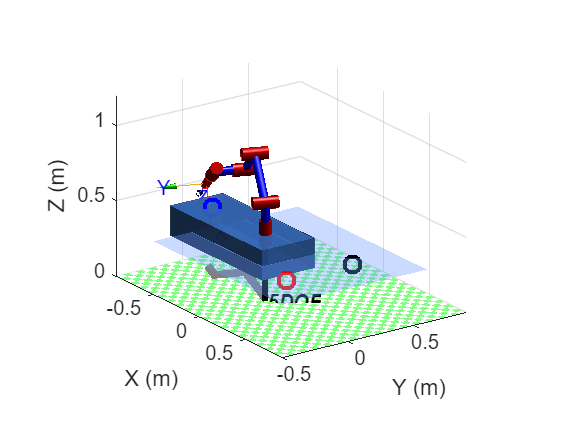

v = VideoWriter('hav_sweep_boat.mp4','MPEG-4');
v.FrameRate = 60;
open(v);

fig = figure('Color','w','Name','Motion planning example');
robot.plot(q_traj(1,:), ...
    'workspace', [-0.9 0.9 -0.5 0.9 0 1.2], ...
    'view', [55 20], 'scale', 0.6);
hold on;

% Tegn båt
patch('Vertices', verts, 'Faces', faces, ...
      'FaceColor', [0.2 0.4 0.7], ...
      'FaceAlpha', 0.9, ...
      'EdgeColor', 'none');

% Tegn vannflate
[Xs, Ys] = meshgrid(-0.5:0.05:0.9, -0.6:0.05:0.6);
water_level = boat_z_offset + boat_height/2; % Juster høyden på vannet etter båtens plassering
Zs = zeros(size(Xs)) + water_level;
surf(Xs, Ys, Zs, 'FaceColor',[0.4 0.6 1], 'FaceAlpha',0.35, 'EdgeColor','none');

% Markerer hovedpunktene
plot3(x_center, y_left,  z_level,  'ro','MarkerSize',8,'LineWidth',2);  % start plukk
plot3(x_center, y_right, z_level,  'ko','MarkerSize',8,'LineWidth',2);  % slutt plukk
plot3(x_start,  y_start, z_start,  'bo','MarkerSize',8,'LineWidth',2);  % opprinnelig start

grid on;
light('Position',[1 1 1],'Style','infinite');
material shiny;
xlabel('X (m)'); ylabel('Y (m)'); zlabel('Z (m)');

% Animer og lagre video
for i = 1:size(q_traj,1)
    robot.animate(q_traj(i,:));
    drawnow;
    frame = getframe(fig);
    writeVideo(v, frame);
end


close(v);
fprintf('Video lagret som hav_sweep_boat.mp4\n');

Video lagret som hav_sweep_boat.mp4
